R(1) = Link('d', 0, 'a', 0, 'alpha', pi/2);
R(2) = Link('d', 0, 'a', 0.1048, 'alpha', 0);
R(3) = Link('d', 0, 'a', 0.1048, 'alpha', 0);
R(4) = Link('d', 0, 'a', 0.07576, 'alpha', 0);

Tool= [0  0 1 0.02;
       0 -1 0 0;
       1  0 0 0;
       0  0 0 1]; 


Offset = [0 pi/2 0 0]; 
World = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; 
PincherII = SerialLink(R, 'name', 'PhantomII','tool',Tool,'offset',Offset,'base',World)

 
PincherII = 
 
PhantomII:: 4 axis, RRRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.1048|          0|     1.5708|
|  3|         q3|          0|     0.1048|          0|          0|
|  4|         q4|          0|    0.07576|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0.02, 0, 0), RPY/xyz = (0, 90, 180) deg            
 


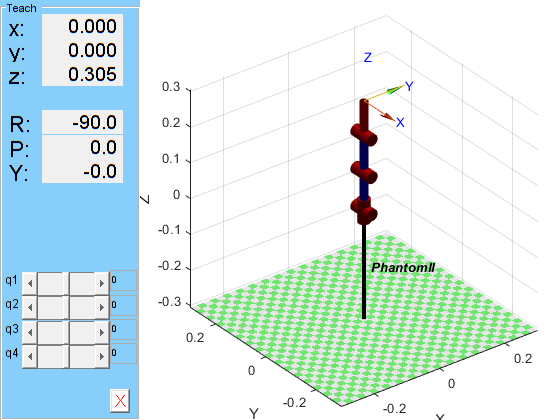

q = [0 0 0 0];
PincherII.plot(q);
PincherII.teach();

H01=eye(4)*trotx(90)

H01 =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


H02=H01*transl(0,0.1048,0)*trotz(90)

H02 =          0   -1.0000         0         0
         0         0   -1.0000         0
    1.0000         0         0    0.1048
         0         0         0    1.0000


H03=H02*transl(0.1048,0,0)

H03 =          0   -1.0000         0         0
         0         0   -1.0000         0
    1.0000         0         0    0.2096
         0         0         0    1.0000


H04=H03*transl(0.07576,0,0)

H04 =          0   -1.0000         0         0
         0         0   -1.0000         0
    1.0000         0         0    0.2854
         0         0         0    1.0000


H0TCP=H04*transl(0.02,0,0)*trotx(180)*troty(90)

H0TCP =          0    1.0000         0         0
   -1.0000         0         0         0
         0         0    1.0000    0.3054
         0         0         0    1.0000


%Poses robot
%Home
artHome = [0 0 0 0]; %Posición de reposo
PincherII.plot(artHome)

art1=[25 25 20 -20]*(pi/180)

art1 =     0.4363    0.4363    0.3491   -0.3491


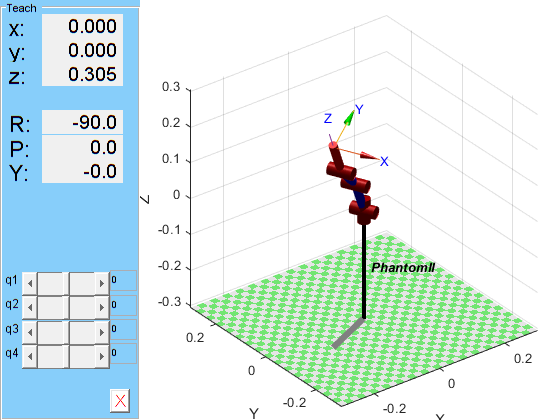

PincherII.plot(art1)

art2=[-35 35 -30 30]*(pi/180)

art2 =    -0.6109    0.6109   -0.5236    0.5236


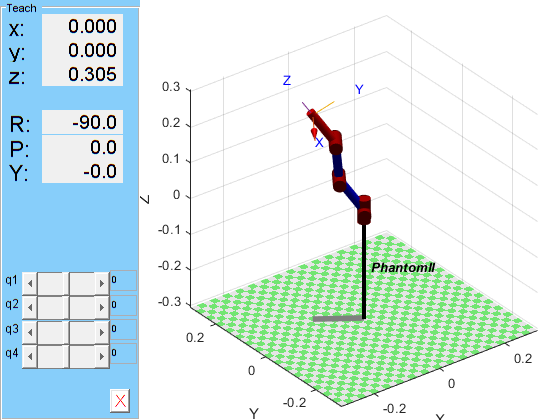

PincherII.plot(art2)

art3=[85 -20 55 25]*(pi/180)

art3 =     1.4835   -0.3491    0.9599    0.4363


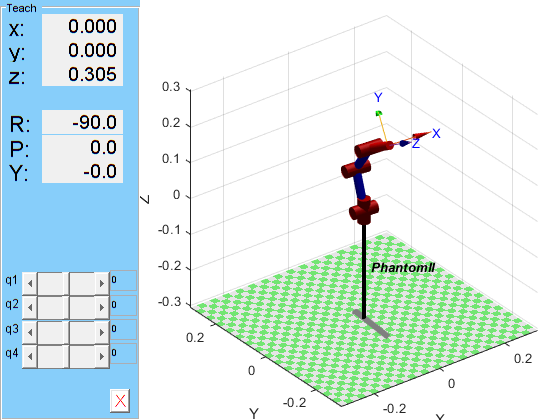

PincherII.plot(art3)

art4=[80 -35 55 -45]*(pi/180)

art4 =     1.3963   -0.6109    0.9599   -0.7854


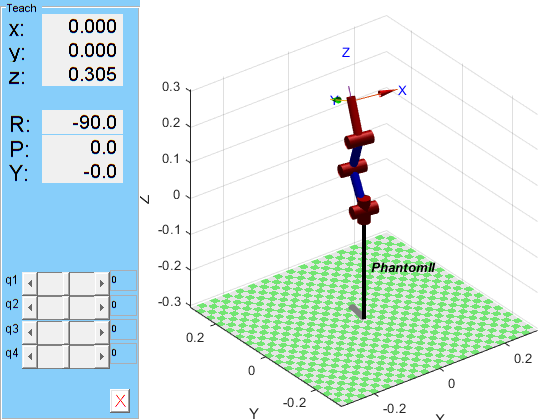

PincherII.plot(art4)